dataPath = 'map2\';        % 路径
dataDir = dir([dataPath '*.txt']); 
Cell_MAX = 8;
for i = 1:length(dataDir)         
    data = importdata([dataPath dataDir(i).name]);
end

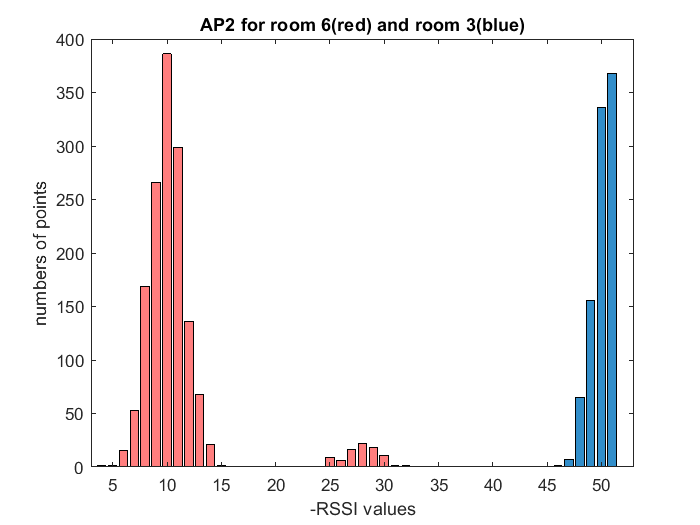

for i = 1:length(dataDir)         
    for j = 1:Cell_MAX
        data = importdata([dataPath dataDir(i).name]);
        if(i == 5 && j == 1)
            figure
            bar(data(3,30:80), 'FaceAlpha',0.8)
            hold on
            bar(data(6,30:80), 'r', 'FaceAlpha',0.5)
            ylabel("numbers of points");
            xlabel("-RSSI values");
            title("AP2 for room 6(red) and room 3(blue)");
            xlim([3 53]);
        end
        
    end
end

dataPath = 'map1\';        % 路径
dataDir = dir([dataPath '*.txt']); 
Cell_MAX = 8;
for i = 1:length(dataDir)         
    data = importdata([dataPath dataDir(i).name]);
end

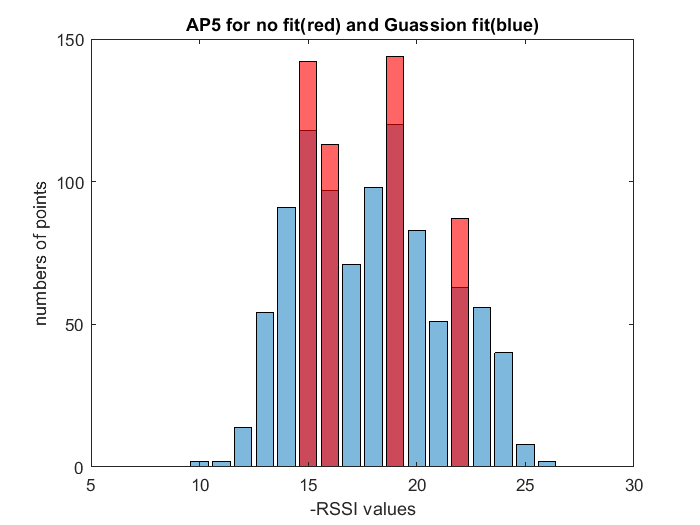

       
    for j = 1:Cell_MAX
        data1 = importdata([dataPath dataDir(1).name]);
        data2 = importdata([dataPath dataDir(2).name]);
        if(j == 1)
            figure
            bar(data1(j,30:80), 'FaceAlpha',0.5)
            hold on
            bar(data2.data(j,30:80), 'r', 'FaceAlpha',0.6)
            ylabel("numbers of points");
            xlabel("-RSSI values");
            title("AP5 for no fit(red) and Guassion fit(blue)");
            xlim([5 30]);
            % ylim([-0.4 0.8])
        end
        
    end